# `Ch5_8_4`

线性相位FIR数字滤波器的特点

实现情况4

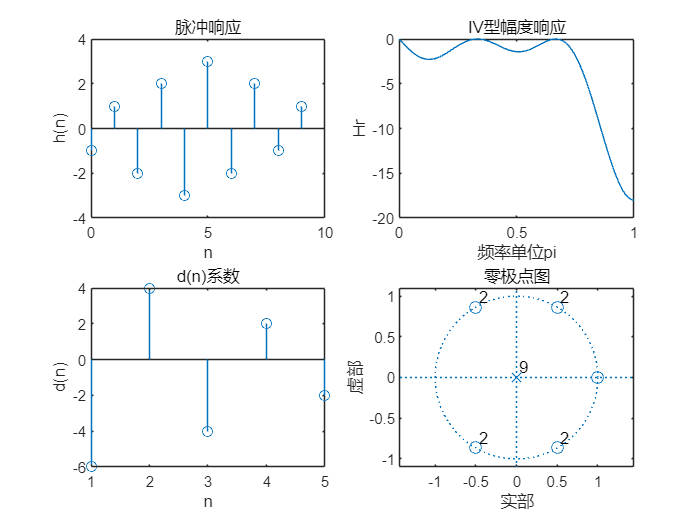

h = [-1 1 -2 2 -3 3 -2 2 -1 1];
M = length(h);
n = 0:M-1;
[Hr,w,d,L] = hr_type4(h);
subplot(2,2,1); stem(n,h); 
xlabel('n'); ylabel('h(n)'); title('脉冲响应')
subplot(2,2,2); plot(w/pi,Hr); 
xlabel('频率单位pi'); ylabel('Hr'); title('IV型幅度响应')
subplot(2,2,3); stem(1:L,d); 
xlabel('n'); ylabel('d(n)'); title('d(n)系数')
subplot(2,2,4); zplane(h,1); title('零极点图')